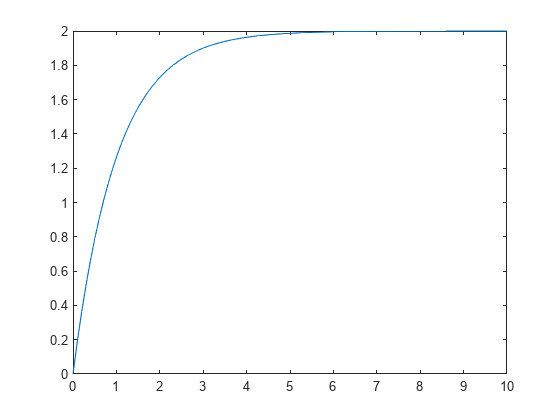

clear

R=1;
C=1;
N=100;
I1=[ones(1,N);ones(1,N)];
A=-1/(R*C);
B=[1/C,1/R*C];
C=1;
D=0;

sys=ss(A,B,C,D);
t = linspace(0, 10, N);
[y, t, x] = lsim(sys, I1',t);
plot(t,y)

clear
load('data.mat')
compressor = data.compressor;
x=data.compressor;
[x,~]=GetRidOfNans(x);
N=length(x);
t = linspace(0,N/0.5,N);
x=[x,ones(N,1)];

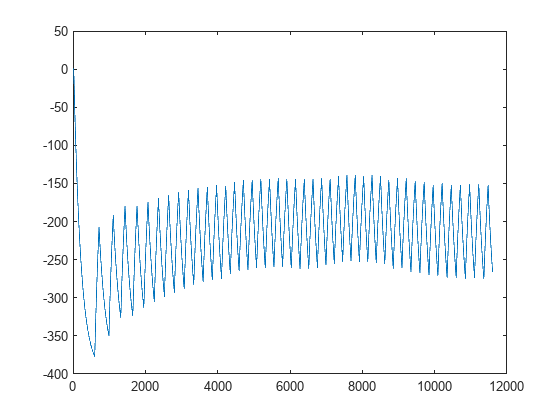


R=400;
C=1;
A=-1/(R*C);
B=[-1/C,1/R*C];
C=1;
D=0;
sys=ss(A,B,C,D);
[y, t, x] = lsim(sys, x',t);
plot(y)

SondaSterujca = data.SondaSterujca;
[y2,~]=GetRidOfNans(SondaSterujca);
plot(y)

clear
load('data.mat')
compressor = data.compressor;
x=data.compressor;
[x,~]=GetRidOfNans(x);
N=length(x);
t = linspace(0,N/0.5,N);
R=400;
C=5;
Ta=1;
G=1;
Ta=Ta*ones(N,1);
y=ModelFunction(x,Ta,G,R,C,t);

% syms Vc
% eq1=eqTransform(Vc)
% clear Vc
% R=1;
% C=1;
% Va=1;
% dVc=0;
% I1=[0,ones(1,10)];
% Vc(1)=Va+I1(1)*R-C*R*dVc;
% for i=2:length(I1)
%     Vc(i)=Va+I1(i)*R-C*R*dVc;
%     dVc=Vc(i)-Vc(i-1);
% end
% function e1 = eqTransform(x)
% syms R C dVc Vc Va I1
% 
% eq1= R*C*dVc+Vc-Va==R*I1;
% 
% e1=isolate(eq1,x);
% end